clear
clf

[z, dim] = ReadArcGrid('merced');

% The struct variable dim contains fields describing the coordinates and
% dimensions of Z. These are based on the information extracted from the
% grid file header.
dx = abs(dim.x(2) - dim.x(1)); % grid spacing in the x-direction
dy = abs(dim.y(2) - dim.y(1)); % grid spacing in the y-direction
[Ny Nx] = size(z); % grid dimensions 
x=dim.x-min(dim.x);
y=dim.y-min(dim.y);

% Detrend
Zo = z; % Save the original elevations for later
z = nanDetrend(z);
plane = Zo - z; % Save the least-squares plane for re-trending later


## FILTERING

## Separate rasters into high-pass and low-pass filtered components

$1\sigma =68\ldotp 27%$, $2\sigma =95\ldotp 45%$, $3\sigma =99\ldotp 73%$ of data.

Gaussian frequency response $\hat{G} \left(f\right)$ is essentially zero by $3\sigma_f$.

Gaussian standard deviation $\sigma$ and frequency response standard deviation $\sigma_f$ are related by: $\sigma_f =\frac{1}{2\pi \sigma }$. 

Spatial wavelength $\lambda =\frac{1}{f}$ where $f$ is frequency is $\frac{\textrm{cycles}}{\left\lbrack L\right\rbrack }$. 

Therefore, the wavelength by which amplitude is nearly fully attenuated is $\lambda_0 =\frac{2\pi \sigma }{3}$.

Hence, to fully attenuate all wavelengths $<\lambda {\;}_0$, use $\sigma_f ~\frac{f_0 }{3}=\frac{1}{3\lambda_0 }\to \sigma =\frac{3\lambda_0 }{2\pi }$. 

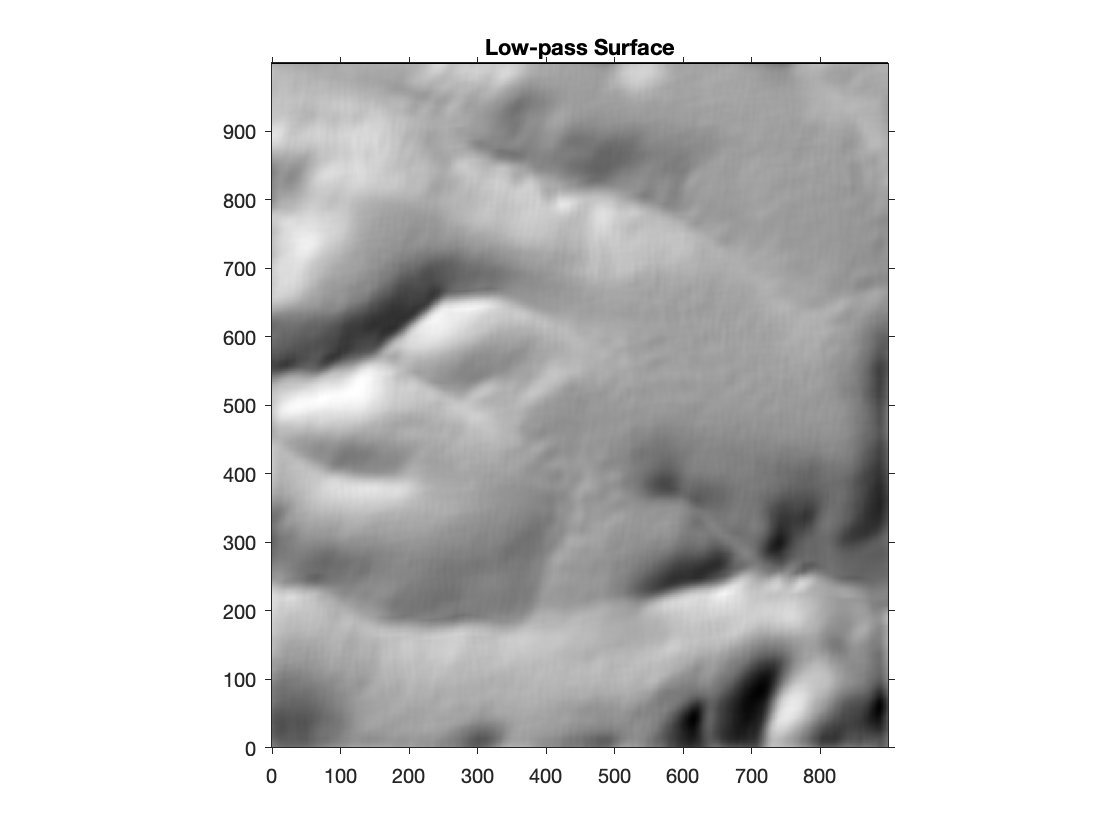

lambda0=18; %wavelength separating high and low frequencies (in m)
sigma=round(3*lambda0/(2*pi)./dx); %calculate gaussian sigma value
hsize=3.*sigma;
hsize = 2*floor(hsize/2)+1; %make sure hsize is an odd integer

%Filter
[zlp,zhp]=nangaussfilt(z,hsize,sigma);

% Display shaded relief maps of the low-pass- and high-pass-filtered data

figure(1);clf
ShadePlot(x,y,zlp); title('Low-pass Surface')

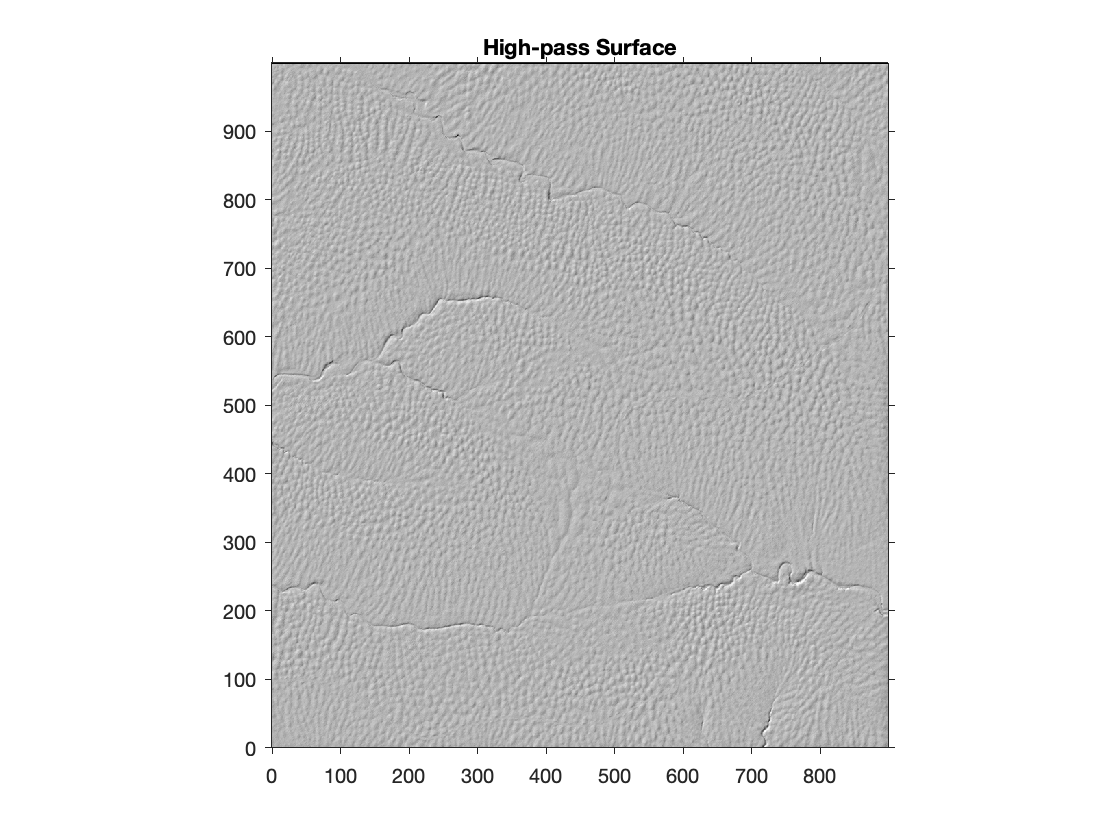

figure(2);clf
ShadePlot(x,y,zhp); title('High-pass Surface')

Pull out a random row and column of **z** and treat them as 1D sample vectors to make test periodograms:

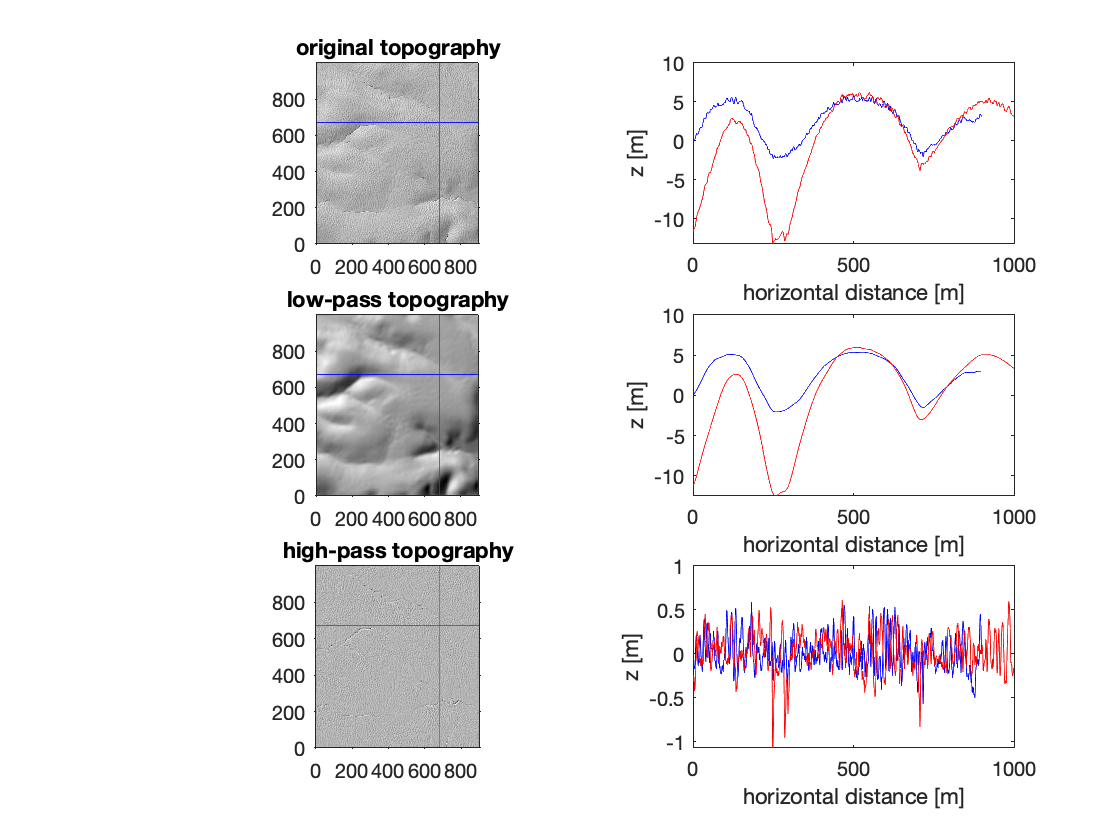


%Select a random row (yr) and column (xr) of z
yr = randi(length(y));
xr = randi(length(x));
zx=z(yr,:);
zy=z(:,xr);
zxhp=zhp(yr,:);
zxlp=zlp(yr,:);
zyhp=zhp(:,xr);
zylp=zlp(:,xr);


figure(3)
clf
%Show surface again with lines showing random transect locations + transect topography
subplot(3,5,1:3); shadetransects(x,y,z,xr,yr);
title('original topography')
subplot(3,5,4:5); topotransects(x,y,zx,zy);

subplot(3,5,5+[1:3]); shadetransects(x,y,zlp,xr,yr);
title('low-pass topography')
subplot(3,5,5+[4:5]); topotransects(x,y,zxlp,zylp);

subplot(3,5,10+[1:3])
shadetransects(x,y,zhp,xr,yr);
title('high-pass topography')
subplot(3,5,10+[4:5]); topotransects(x,y,zxhp,zyhp);

## 1D Transect Periodograms

Start with just 1D periodograms of the random row and column of z above.

Calculate the periodogram for each random transect.

% Identify the spatial sampling frequency
fs = 1/dx; %units of samples/meter
fNyquist = fs/2; %Nyquist frequency 
fx = 0:fs/Nx:fNyquist;%frequency vector
fy = 0:fs/Ny:fNyquist;%frequency vector
wx = 1./fx; %wavelengths
wy = 1./fy; %wavelengths
f=fy;
w=wy;

%Calculate 1D, 1-sided power spectra and amplitude spectra using fft
[Afxx,Pfxx] = fft1side(zx);
[Afyy,Pfyy] = fft1side(zy);


%Calculate a 1D periodogram for each of these random samples
% windowx = hamming(length(zx)); %create hamming window to taper signal and avoid edge artifacts
[Pxx,Plxx,Axx,Alxx] = per1s(zx,fx,fs);
[Pyy,Plyy,Ayy,Alyy] = per1s(zy,fy,fs);
[Pxxhp,Plxxhp,Axxhp,Alxxhp] = per1s(zxhp,fx,fs);
[Pyyhp,Plyyhp,Ayyhp,Alyyhp] = per1s(zyhp,fy,fs);
[Pxxlp,Plxxlp,Axxlp,Alxxlp] = per1s(zxlp,fx,fs);
[Pyylp,Plyylp,Ayylp,Alyylp] = per1s(zylp,fy,fs);

*Note that while we selected a random row (y value), this extracts a sample that varies in x (i.e., across multiple columns). Hence Pxx is a periodogram over x, while Pyy is a periodogram over y.*

#### Plot the periodograms:

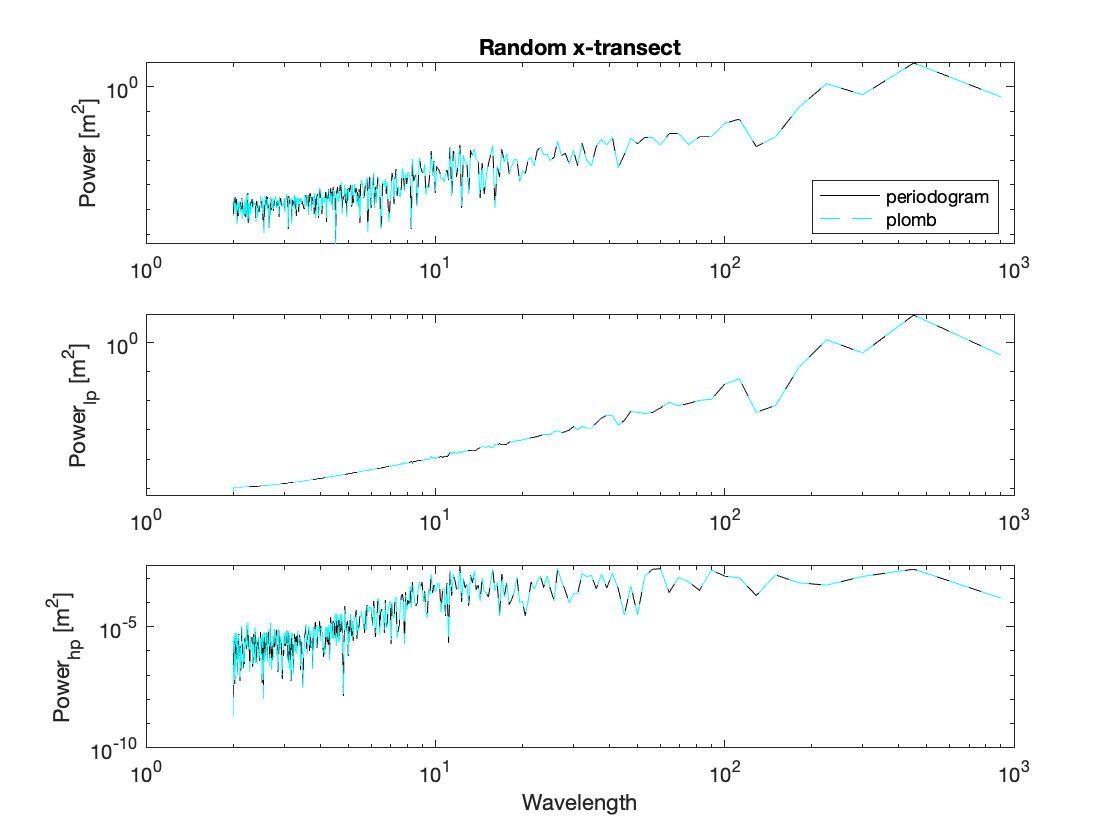

figure(4);clf
plotspectpass(Pxx,Plxx,Pxxlp,Plxxlp,Pxxhp,Plxxhp,wx,'Random x-transect',[]);

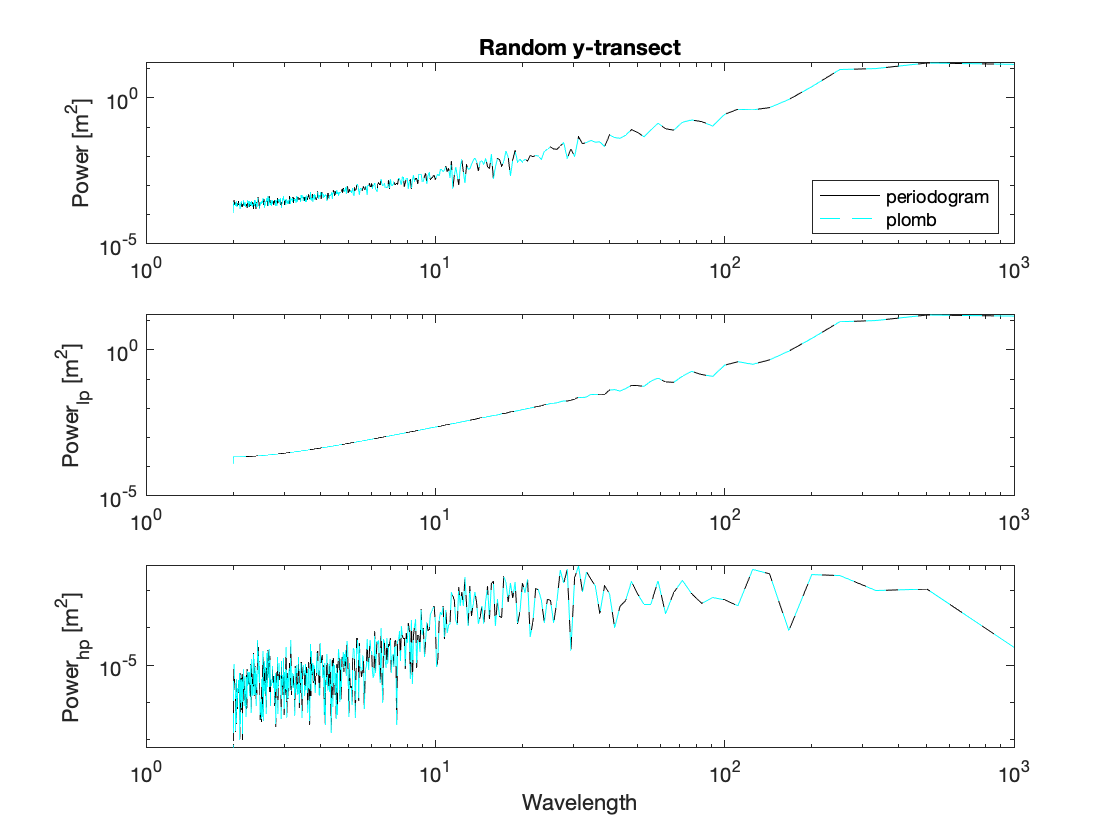


figure(5);clf
plotspectpass(Pyy,Plyy,Pyylp,Plyylp,Pyyhp,Plyyhp,wy,'Random y-transect',[]);

## 1D Holes

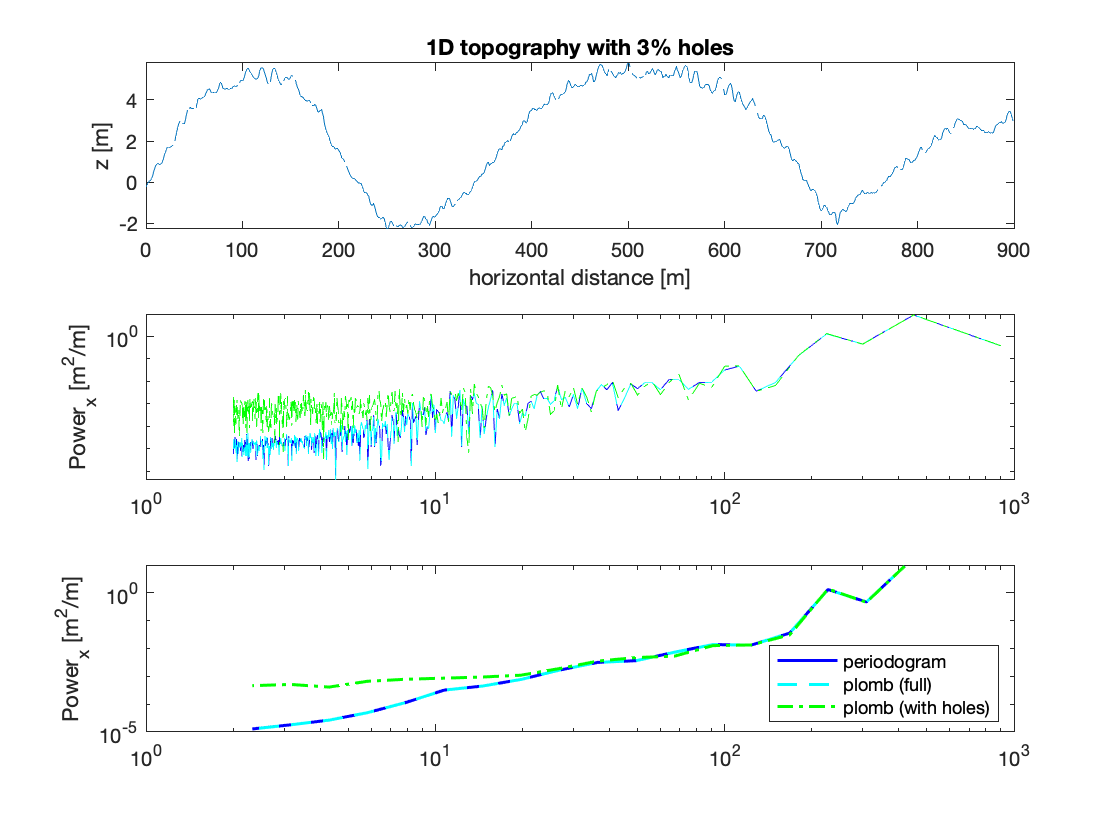

prcholes = 0.03; %Percent of transect points to turn into holes (NaNs)
ttext = ['1D topography with ',num2str(prcholes*100),'% holes'];


figure(8); clf
[Plxxh,Alxxh,~,~,~] = holebinspec(prcholes,x,zx,fx,Pxx,Plxx,fs,ttext);

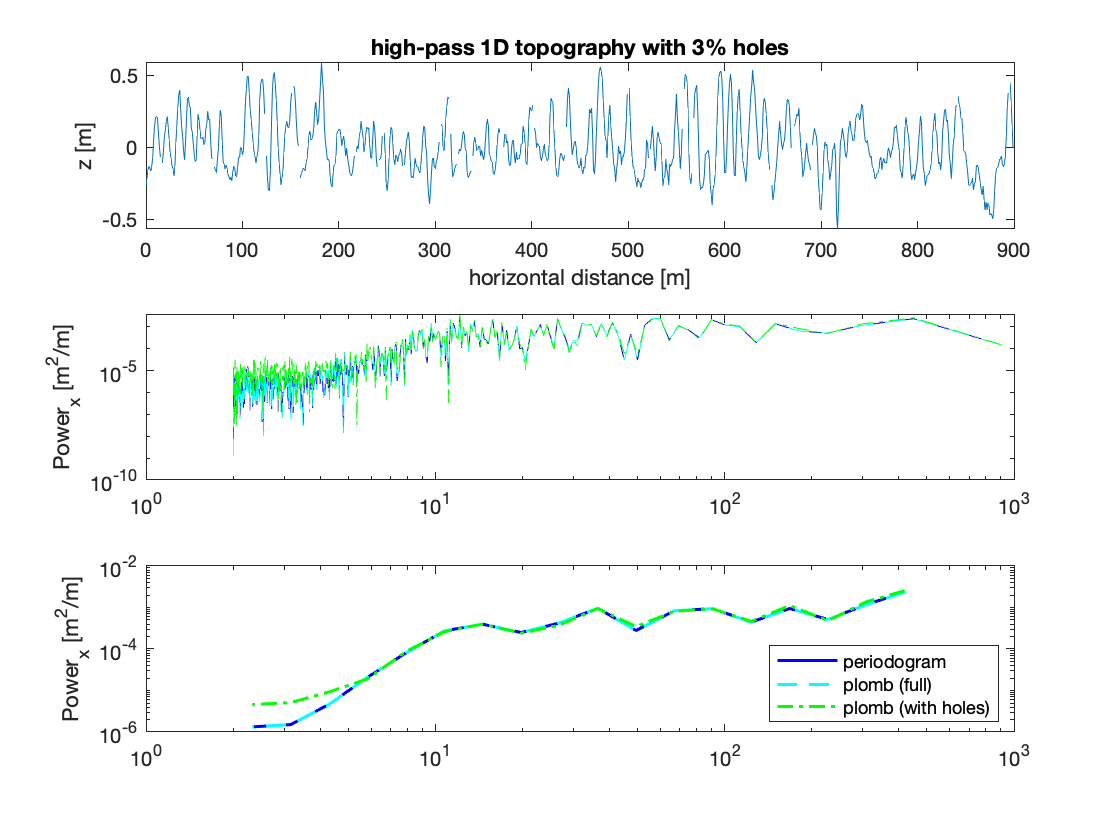


figure(9); clf
[Plxxhph,Alxxhph,~,~,~] = holebinspec(prcholes,x,zxhp,fx,Pxxhp,Plxxhp,fs,['high-pass ',ttext]);


figure(10);clf
[Plxxlph,Alxxlph,~,~,~] = holebinspec(prcholes,x,zxlp,fx,Pxxlp,Plxxlp,fs,['low-pass ',ttext]);

## Average spectra

We can also make average spectra in the x and y directions to examine the difference in mean directional roughness.

%Calculate average periodograms of all columns and rows in z
[Pxavg,Plxavg,Axavg,Alxavg,Pyavg,Plyavg,Ayavg,Alyavg] = plombperav(z,fx,fy,fs);
[Pxhpavg,Plxhpavg,Axhpavg,Alxhpavg,Pyhpavg,Plyhpavg,Ayhpavg,Alyhpavg] = plombperav(zhp,fx,fy,fs);
[Pxlpavg,Plxlpavg,Axlpavg,Alxlpavg,Pylpavg,Plylpavg,Aylpavg,Alylpavg] = plombperav(zlp,fx,fy,fs);

#### Plot Average Spectra

figure(11);clf
plotspectpass(Pxavg,Plxavg,Pxlpavg,Plxlpavg,Pxhpavg,Plxhpavg,wx,'Averaged X-Transects',[])

figure(12);clf
plotspectpass(Pyavg,Plyavg,Pylpavg,Plylpavg,Pyhpavg,Plyhpavg,wy,'Averaged Y-Transects',[])

#### Average Spectra with Holes

prcholes = 0.025; %Percent of DEM to turn into holes (NaNs)
zh = holes(prcholes,z);
%Plot the hillshade showing holes
figure(13);clf
ShadePlot(x,y,zh); title(['Surface with ',num2str(prcholes),'% holes'])

[Plxhavg,~,Plyhavg,~] = holespec2D(prcholes,z,fx,fy,fs);
[Plxlphavg,~,Plylphavg,~] = holespec2D(prcholes,zlp,fx,fy,fs);
[Plxhphavg,~,Plyhphavg,~] = holespec2D(prcholes,zhp,fx,fy,fs);

#### Plot Average Spectra with Holes

figure(14);clf

plotspectpass(Plxavg,Plxhavg,Plxlpavg,Plxlphavg,Plxhpavg,Plxhphavg,wx,['Averaged X-Transects with ',num2str(prcholes),'% Holes'],{'plomb','plomb with holes'});

figure(15);clf
plotspectpass(Plyavg,Plyhavg,Plylpavg,Plylphavg,Plyhpavg,Plyhphavg,wy,['Averaged Y-Transects with ',num2str(prcholes),'% Holes'],{'plomb','plomb with holes'});

## 2D Spectra **WORKING ON THIS NOW

% Calculate the power spectrum using the 2D Fast Fourier Transform (FFT).
% Note that the zero padding and windowing happen inside fft2D.
[Pm fm Pv fv] = fft2D(zhp,dx,dy,0,0); 

% [zhpw Wss] = Hann2D(zhp);
%Use pad2D and Hann2D once fftshift is figured out

[~,~,Ayy,Alyy,fyy,flyy] = per1s(zhp,fy,fs);

Ayy = [Ayy;flipud(Ayy(Ny-mod(Ny,),:))]

 A = A2(1:(N-mod(N,2))/2+1); %calculate 1-sided amplitude spectrum (if N=odd, subtract 1 and divide; if even, divide in half; always add 1 for DC component)
    A(2:(end-mod(N-1,2))) = 2.*A(2:(end-mod(N-1,2))); %fold aliased amplitude from duplicate frequencies
    A(1) = 0; %zero out DC component (signal mean)

[~,Axy] = periodogram1s(Ayy.',fx,fs);
[~,Alxy] = plomb1s(Alyy.',fx,fs);

Axy = Axy.';
Alxy = Alxy.';

Pxyhp = Axy.*conj(Axy);
Plxyhp = Alxy.*conj(Axy);


[Fx,Fy] = meshgrid(fx,fy); % matrices of column and row indices
Fxy = sqrt((Fx).^2 + (Fy).^2); % frequency matrix

fsort = sortrows(horzcat(Fxy(:),Pxyhp(:),Plxyhp(:)),1);
fxy = fsort(:,1);
pxy = fsort(:,2);
plxy = fsort(:,3);


% Plot
figure(18);clf
% set(f1,'Name','1D Spectrum','NumberTitle','off');

subplot(3,1,1)
[axff afxw] = SpecPlot1D(fv,Pv);
title('fft2D')

subplot(3,1,2)
[axpf axpw] = SpecPlot1D(fxy,pxy);
% set(axpf,'xlim',get(axff,'xlim'),'ylim',get(axff,'ylim'))
title('2D periodogram');

subplot(3,1,3)
[axpf axpw] = SpecPlot1D(fxy,plxy);
% set(axpf,'xlim',get(axff,'xlim'),'ylim',get(axff,'ylim'))
title('2D plomb');


figure(19);clf
SpecPlot2D(fm,log10(Pm));

figure(20);clf
SpecPlot2D(Fxy,log10(Pxyhp));

figure(21);clf
SpecPlot2D(Fxy,log10(Plxyhp));


## Functions

#### SPECTRAL CALCULATION FUNCTIONS

function [A,P] = fft1side(z)
    N=numel(z);
    Z = fft(z); %compute fourier transform
    A2 = abs(Z./N); % normalize by number of samples (i.e., multiply by width or sample interval) for 2-sided amplitude spectrum
    A = A2(1:(N-mod(N,2))/2+1); %calculate 1-sided amplitude spectrum (if N=odd, subtract 1 and divide; if even, divide in half; always add 1 for DC component)
    A(2:(end-mod(N-1,2))) = 2.*A(2:(end-mod(N-1,2))); %fold aliased amplitude from duplicate frequencies
    A(1) = 0; %zero out DC component (signal mean)
    P = A.^2; %power spectrum
end

    
function [P,A,f] = periodogram1s(z,f,fs)
    [P,f] = periodogram(z,[],f,fs,'power');
    P = 4.*P; %1-sided power spectra
    A = P.^(1/2); %1-sided amplitude spectra
end

function [Pl,Al,f] = plomb1s(z,f,fs)
    [Pl,f] = plomb(z,fs,f,'power');
    Pl = 2.*Pl;
    Al = Pl.^(1/2);
end

function [P,Pl,A,Al,f,fl] = per1s(z,f,fs)
    [P,A,f] = periodogram1s(z,f,fs);
    [Pl,Al,fl] = plomb1s(z,f,fs);
end

function [Plxavg,Alxavg,Plyavg,Alyavg,flx,fly] = plombav(z,fx,fy,fs)
    [Plx,Alx,flx] = plomb1s(z',fx,fs);
    [Ply,Aly,fly] = plomb1s(z,fy,fs);
    Plyavg = mean(Ply,2);
    Plxavg = mean(Plx,2);
    Alyavg = mean(Aly,2);
    Alxavg = mean(Alx,2);
end

function [Pxavg,Axavg,Pyavg,Ayavg,fx,fy] = periodogramav(z,fx,fy,fs)
    [Px,Ax,fx] = periodogram1s(z',fx,fs);
    [Py,Ay,fy] = periodogram1s(z,fy,fs);
    Pyavg = mean(Py,2);
    Pxavg = mean(Px,2);
    Ayavg = mean(Ay,2);
    Axavg = mean(Ax,2);
end

function [Pxavg,Plxavg,Axavg,Alxavg,Pyavg,Plyavg,Ayavg,Alyavg] = plombperav(z,fx,fy,fs)
    [Plxavg,Alxavg,Plyavg,Alyavg] = plombav(z,fx,fy,fs);
    [Pxavg,Axavg,Pyavg,Ayavg] = periodogramav(z,fx,fy,fs);
end

function [B] = logbin(f,P,n)
    nbin = n; % Number of bins
    B = nanbin(log10(f),log10(P),nbin,0); % Bin the log-transformed data
end


function [zp] = pad2D(z)
    Nx = size(z,2);
    Ny = size(z,1);
    Lx = 2.^(ceil(log(max([Nx Ny]))/log(2)));        
    Ly = Lx;
    xdiff = [floor((Lx-Nx)/2) ceil((Lx-Nx)/2)];
    ydiff = [floor((Ly-Ny)/2) ceil((Ly-Ny)/2)];
    zp = [zeros(Ny,xdiff(1)) z zeros(Ny,xdiff(2))];
    zp = [zeros(ydiff(1),size(zp,2)); zp; zeros(ydiff(2),size(zp,2))];
end

#### HOLES FUNCTIONS

function [zh] = holes(prcholes,z)
% prcholes: percent of input points to turn into holes (e.g., 0.5 = 50%)
% z: input array (vector or matrix)
    Nholes = round(prcholes*numel(z));
    eholes = randi(numel(z),[1,Nholes]);
    zh=z;
    zh(eholes)=NaN;   
end


function  [Plh,Alh,B,Bl,Blh] = holebinspec(prcholes,d,z,f,P,Pl,fs,titletext)    
    [zh] = holes(prcholes,z);
    [Plh,Alh] = plomb1s(zh,f,fs);
    n = 20;
    [B,Bl,Blh] = dealC(cellfun(@(a)logbin(f,a,20),{P,Pl,Plh},'UniformOutput',0));

    if nargin > 7
        %Show transect topography
        subplot(3,1,1)
        plot(d,zh);
        xlabel('horizontal distance [m]');
        ylabel('z [m]');
        title(titletext);
        
        %Plot periodograms on loglog axes using wavelength 
        subplot(3,1,2)
        loglog(1./f,P,'b',1./f,Pl,'c--',1./f,Plh,'g-.')
        ylabel('Power_x [m^2/m]');
        
        %Plot binned periodograms
        subplot(3,1,3)
        loglog(1./10.^B(:,1),10.^B(:,2),'b',1./10.^Bl(:,1),10.^Bl(:,2),'c--',1./10.^Blh(:,1),10.^Blh(:,2),'g-.','linewidth',1.5)
        ylabel('Power_x [m^2/m]');
        legend('periodogram','plomb (full)','plomb (with holes)','location','southeast');
    end
end


function [Plxxhavg,Alxxhavg,Plyyhavg,Alyyhavg] = holespec2D(prcholes,z,fx,fy,fs)
    [zh] = holes(prcholes,z);
    [Plxxhavg,Alxxhavg,Plyyhavg,Alyyhavg] = plombav(zh,fx,fy,fs);   
end


#### PLOTTING FUNCTIONS


% Plot hillshade with transect lines
function shadetransects(x,y,z,xr,yr)
    ShadePlot(x,y,z);
    axis xy;
    hold on
    plot([x(1) x(end)],[y(yr) y(yr)],'b',[x(xr) x(xr)],[y(1) y(end)],'r'); %plot a line at each transect location
end

% Plot x and y transect topography
function topotransects(x,y,zx,zy)
    plot(x,zx,'b',y,zy,'r');
    xlabel('horizontal distance [m]')
    ylabel('z [m]')
end

% Plot full, low-pass and high-pass spectra produced by periodogram and plomb
function plotspectpass(P,Pl,Plp,Pllp,Php,Plhp,w,titletext,legendtext)
    if isempty(legendtext)
        legendtext = {'periodogram','plomb'};
    end
    
    subplot(3,1,1)
    loglog(w,P,'k',w,Pl,'c--');
    ylabel('Power [m^2]')
    legend(legendtext,'Location','southeast')
    title(titletext)
    
    subplot(3,1,2)
    loglog(w,Plp,'k',w,Pllp,'c--')
    ylabel('Power_{lp} [m^2]')
    
    subplot(3,1,3)
    loglog(w,Php,'k',w,Plhp,'c--')
    ylabel('Power_{hp} [m^2]')
    xlabel('Wavelength')
end